# EE-414 Speech Processing Lab

#  Lab-7

## Aim 

#### ● To understand the limitation of DTFT for the spectral analysis of speech. 

#### ● To understand the development of short-term Fourier transform (STFT) representation. 

#### ● To understand the difference in the nature of linear and log magnitude spectra. 

#### ● To understand the difference among the spectra of voiced, unvoiced and silence regions of speech. 

#### ● To plot the STFT of a speech signal. 

#### ● To understand the difference between true and convolved spectra. 

#### ● To understand the effect of rectangular, Hamming and Hanning window functions on short term spectral analysis. 

#### ● To understand the effect of frame size on short term spectral analysis

## Introduction:

We did short term processing in time domain by checking the short term energy, ST-ZCR and ST - auto correlation. Similaryly we need to do the short term processing in the frequency domain as well by taking the short term fourier transform as speech signals have frequency components varying with time.

Spectrogram and Waveform of "Speech Signal" from wavesurfer

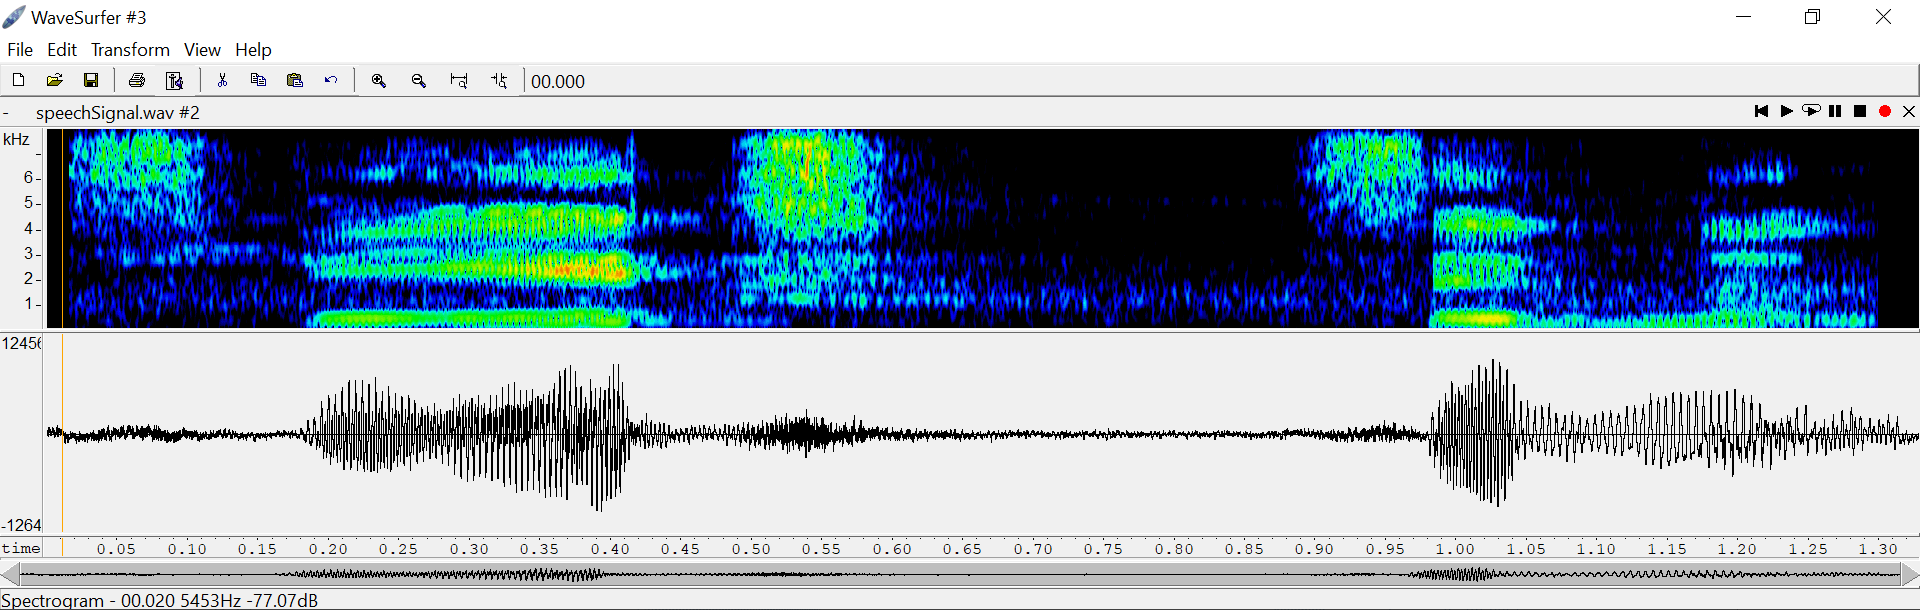

Record (16kHz, 16bit) the word “speech signal”; truncate long silence regions. 

### A. **DTFT and its limitation:**

a. Plot the linear and log magnitude spectrum for the entire speech. 

b. Plot log-magnitude spectrum of voiced, unvoiced and silence regions in the recorded speech and explain the difference between log-spectrum of all three cases. 

c. Comment on the limitation of DTFT. 

#### Theory:

The DTFT is defined as follows:

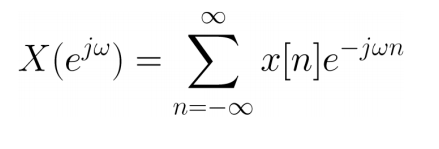

as this is continuous in nature, we cannot represent this in digital systems hence the term DFT came into picture

The DFT is defined as follows:

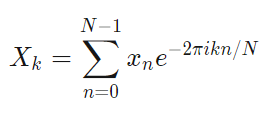

#### Procedure:

We first record and read the original speech signal and plot its frequency spectrum using linear scale and log scale. Then we take the voiced, unvoiced and silence segments and plot its log magnitude spectrum and we then observe the differences.

#### **Code:**

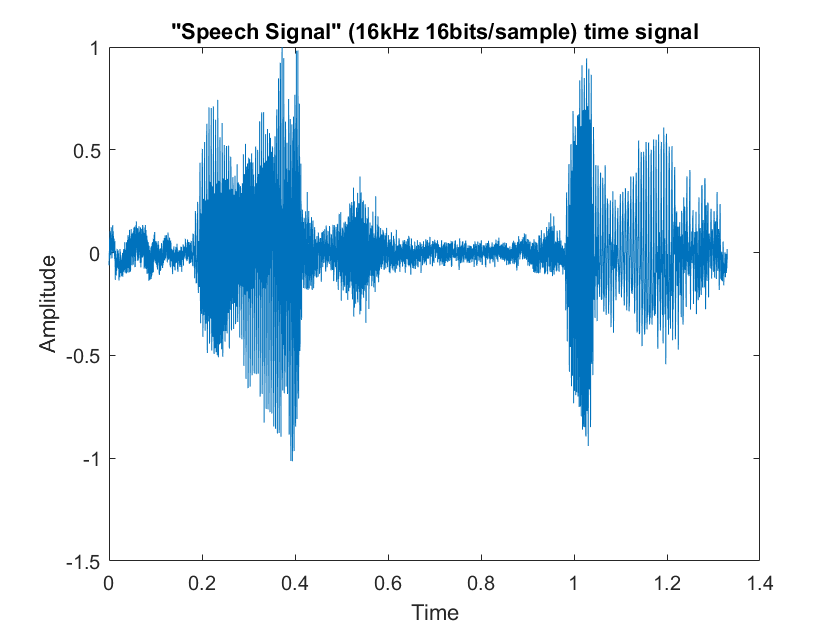

close all; clc; clear all;

[y,fs]=audioread('speechSignal.wav'); 
% sound(y, fs);

sound_sample = y(:,1); % Taking left channel
sound_sample = sound_sample./max(sound_sample); % Normalizing

% "Speech Signal" 
plot_time_signal(sound_sample, fs, '"Speech Signal" (16kHz 16bits/sample) time signal'); 

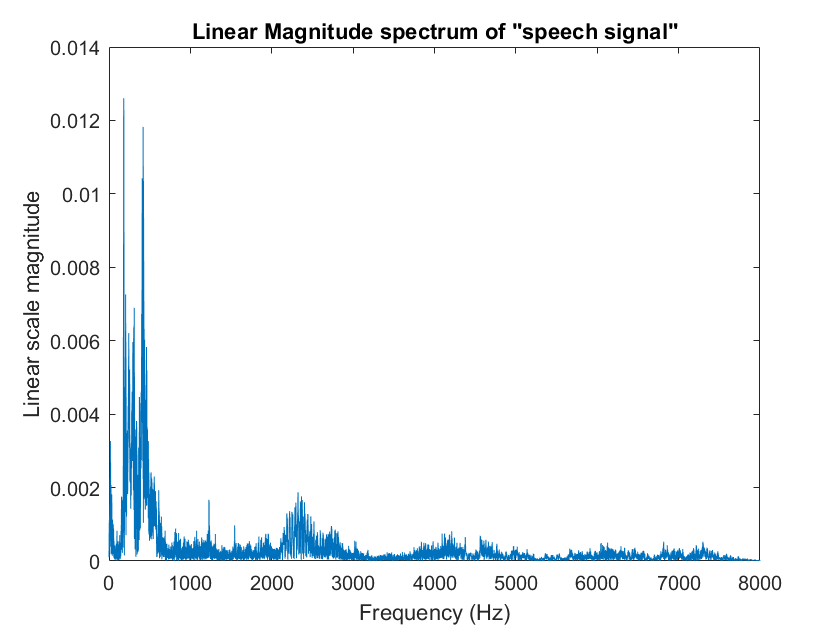


plot_freq_spectrum(sound_sample, fs, 'Linear Magnitude spectrum of "speech signal"', 'linear');

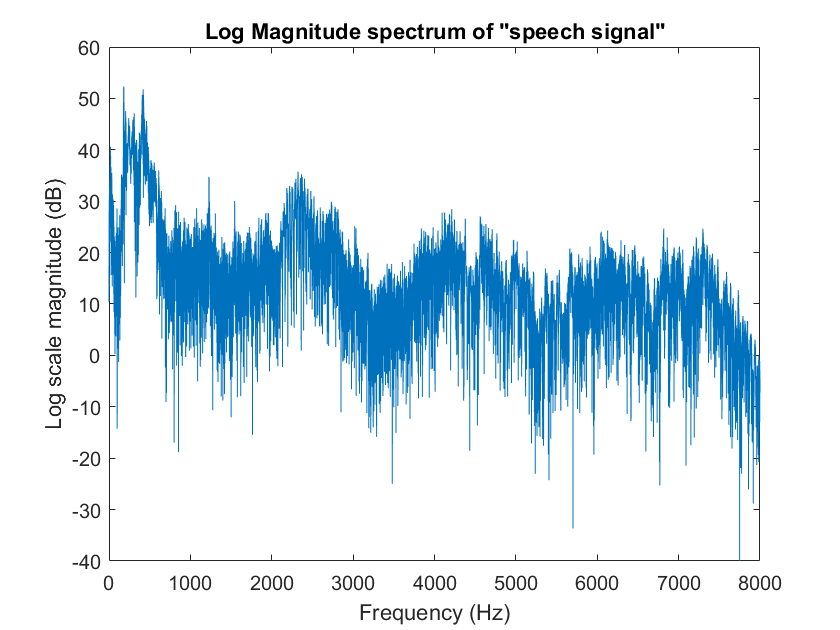


plot_freq_spectrum(sound_sample, fs, 'Log Magnitude spectrum of "speech signal"', 'log');

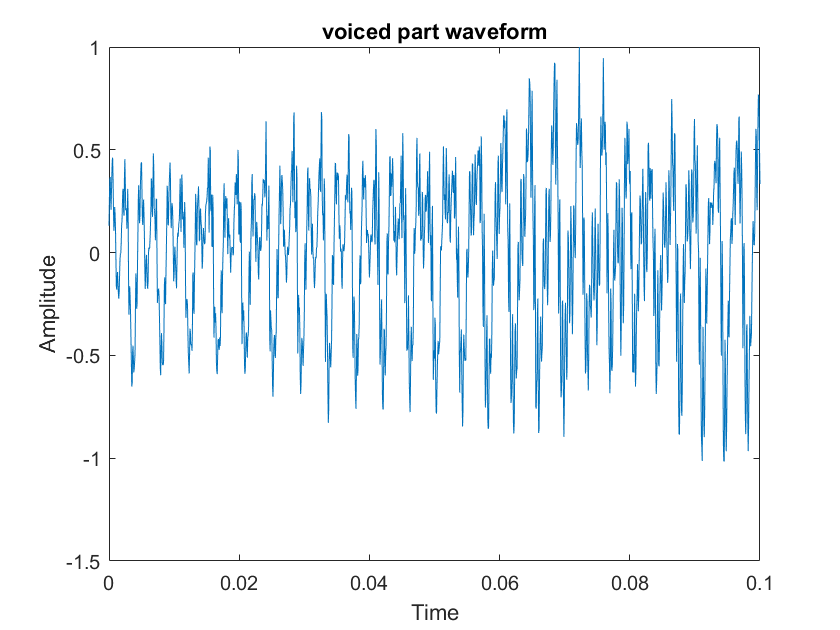

voiced_part = sound_sample(round(0.30*fs):round(0.40*fs));
unvoiced_part = sound_sample(round(0.5*fs):round(0.6*fs));
silence_part = sound_sample(round(0.70*fs):round(0.8*fs));

plot_time_signal(voiced_part, fs, 'voiced part waveform'); 

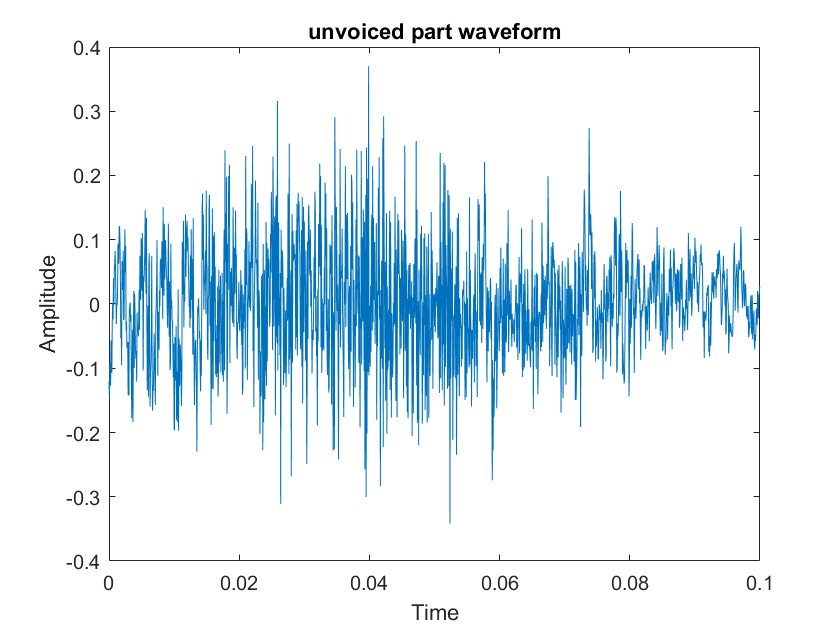

plot_time_signal(unvoiced_part, fs, 'unvoiced part waveform');

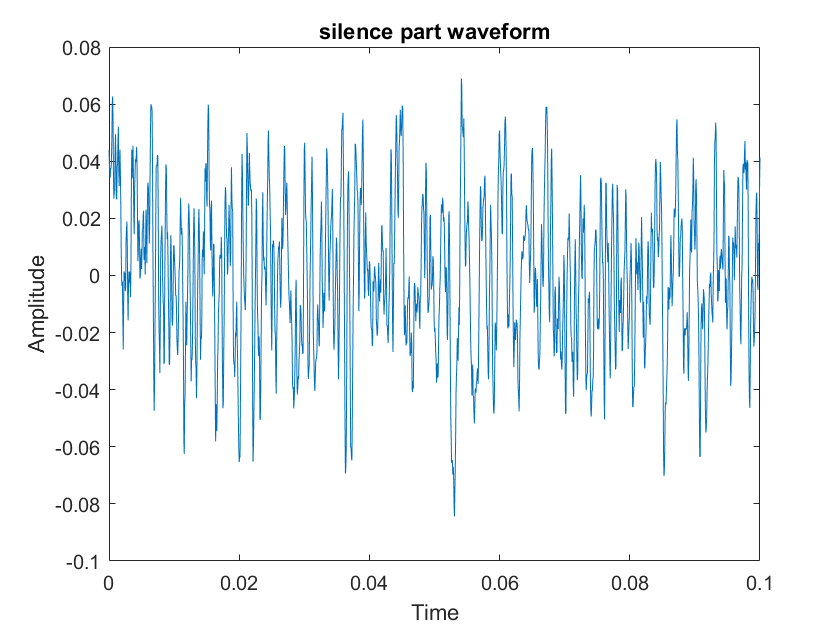

plot_time_signal(silence_part, fs, 'silence part waveform'); 

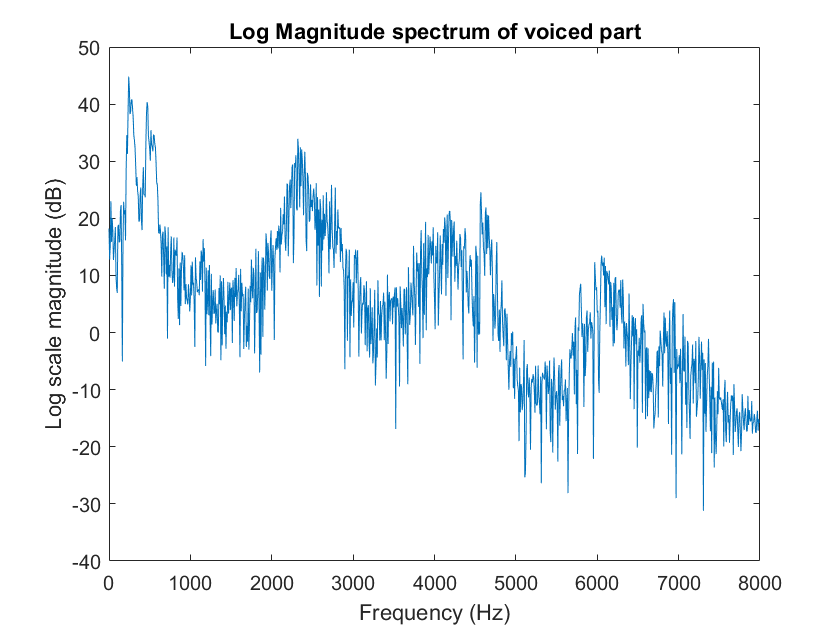


plot_freq_spectrum(voiced_part, fs, 'Log Magnitude spectrum of voiced part', 'log');

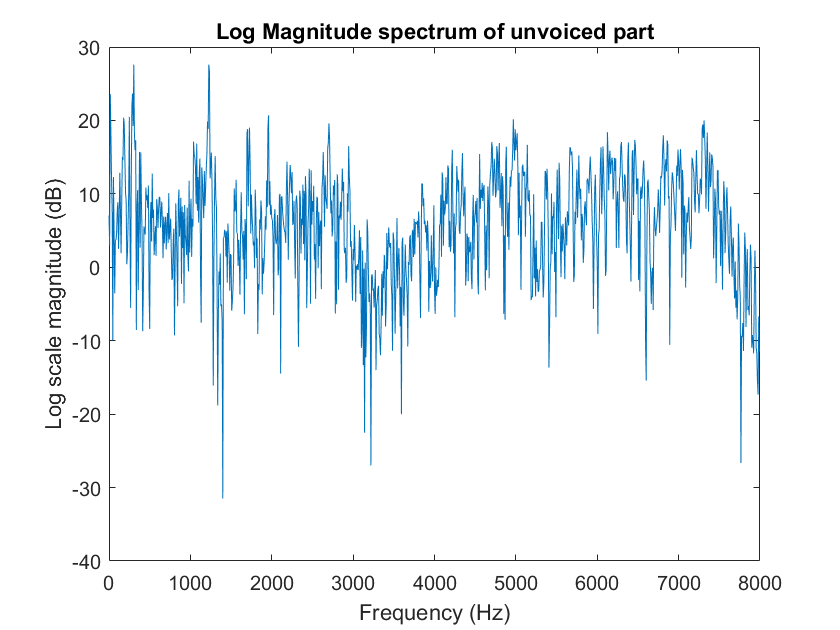

plot_freq_spectrum(unvoiced_part, fs, 'Log Magnitude spectrum of unvoiced part', 'log');

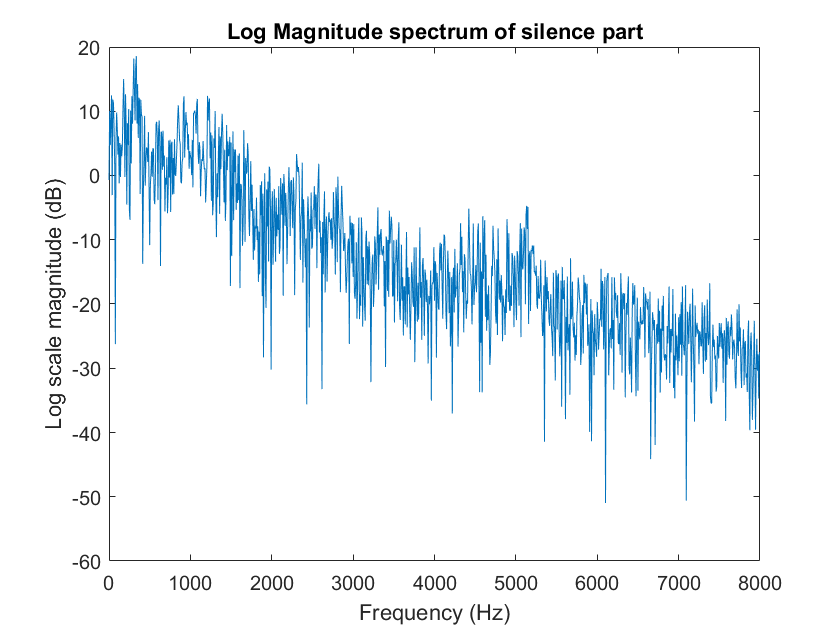

plot_freq_spectrum(silence_part, fs, 'Log Magnitude spectrum of silence part', 'log');

#### Observations:

a) We shall use log magnitude spectrum as we can see both the high and low magnitudes of the frequency components clearly whereas in linear magnitude spectrum we mainly see the larger magnitudes dominating.

b) voiced: We see a decreasing slope in the log magnitude spectrum and harmonic structure is visible

    unvoiced: We see a non-decreasing slope in the log magnitude spectrum

    silence: In my case, we see a decreasing slope.

c) When we take the spectrum (By applying DFT) of the whole signal (which is non-stationary signal), the frequencies of all the components are present in the spectrum, however we have no information regarding when these frequency components actually take place. 

The spectrum is plotted by assuming the given waveform as stationary always, even if the waveform is infact non-stationary. Only by taking intervals of stationarity we are able to observe that the frequency is infact changing with time. So this is the limitation of the fourier transform.

### B. Need for Short Time Fourier Transform(STFT): 

a. How can you solve the above problem using STFT? Plot the STFT of one speech frame at the centre of above three regions. Write your observations.

#### Theory:

Since speech signals are non-stationary, we use STFT to see spectral information, by taking DFT on blocks of speech. There is a frame size and frame shift associated with each of these blocks and each of these blocks will have a corresponding DFT representation.

The equation for STFT is as follows:

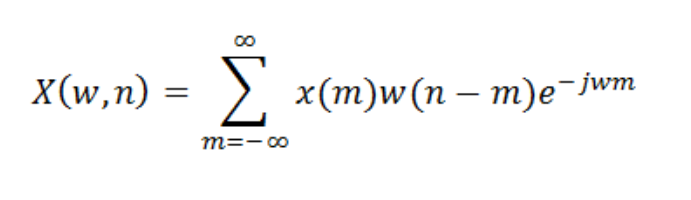 

w(n) is the window function, so x(m)*w(n-m) is the window segment in the time instant 'n'

#### Procedure:

We take a frame around the center of the voiced, unvoiced and silent regions, plot the time domain plots and then plot the corresponding log magnitude spectrums of these regions.

#### **Code:**

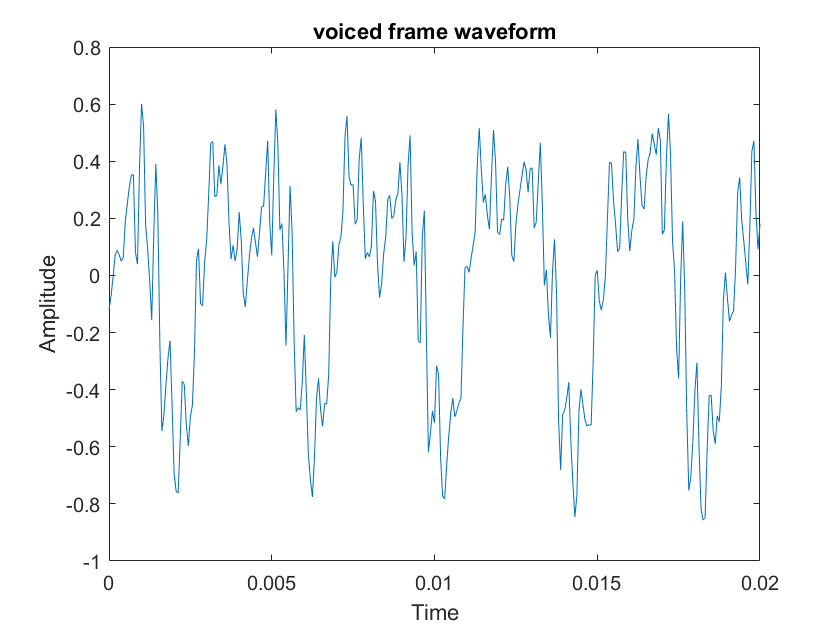

voiced_frame = voiced_part(round(length(voiced_part)/2 - 0.010*fs):round(length(voiced_part)/2 + 0.010*fs));
plot_time_signal(voiced_frame, fs, 'voiced frame waveform'); 

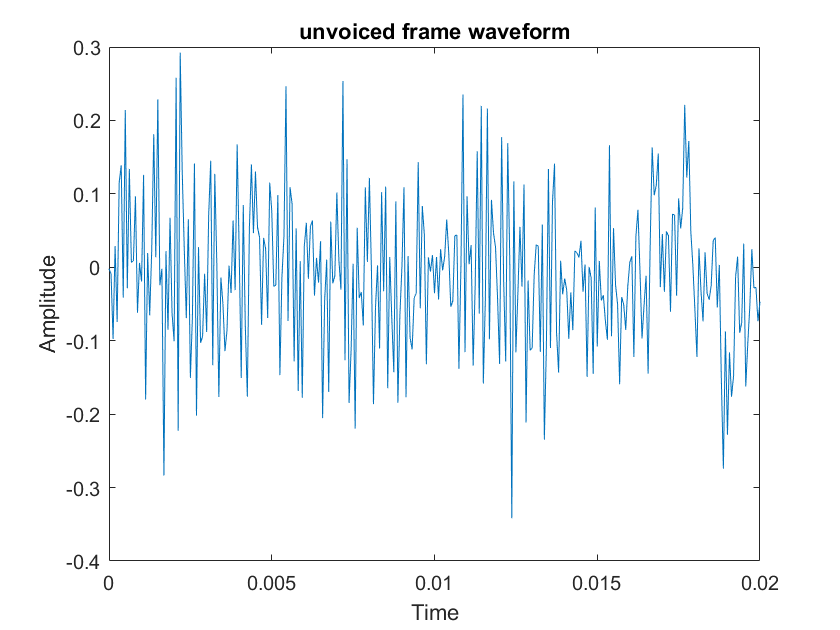


unvoiced_frame = unvoiced_part(round(length(unvoiced_part)/2 - 0.010*fs):round(length(unvoiced_part)/2 + 0.010*fs));
plot_time_signal(unvoiced_frame, fs, 'unvoiced frame waveform'); 

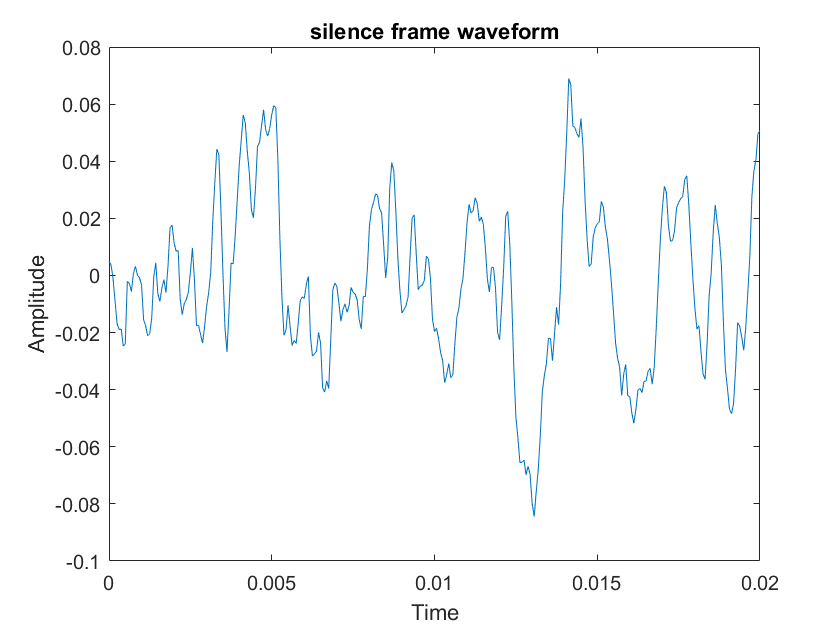


silence_frame = silence_part(round(length(silence_part)/2 - 0.010*fs):round(length(silence_part)/2 + 0.010*fs));
plot_time_signal(silence_frame, fs, 'silence frame waveform'); 

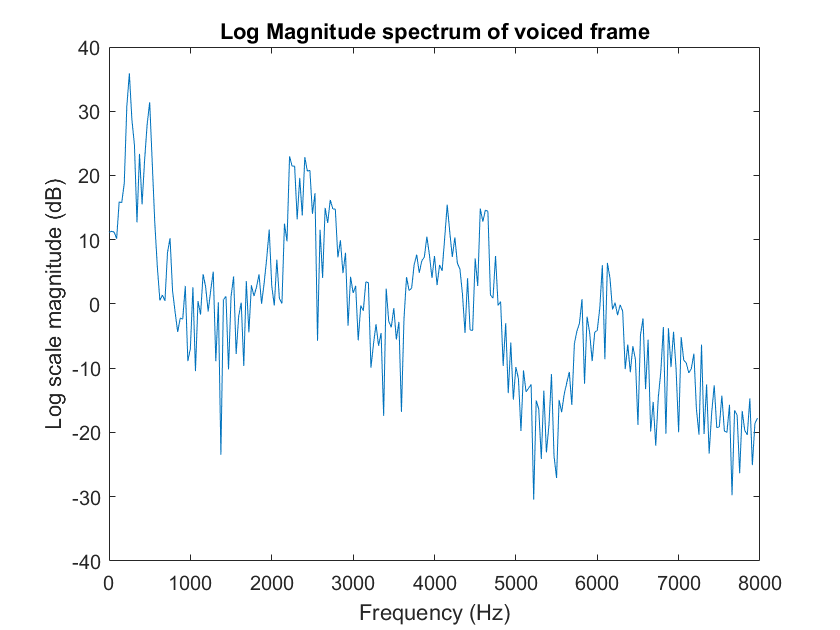


plot_freq_spectrum(voiced_frame, fs, 'Log Magnitude spectrum of voiced frame', 'log');

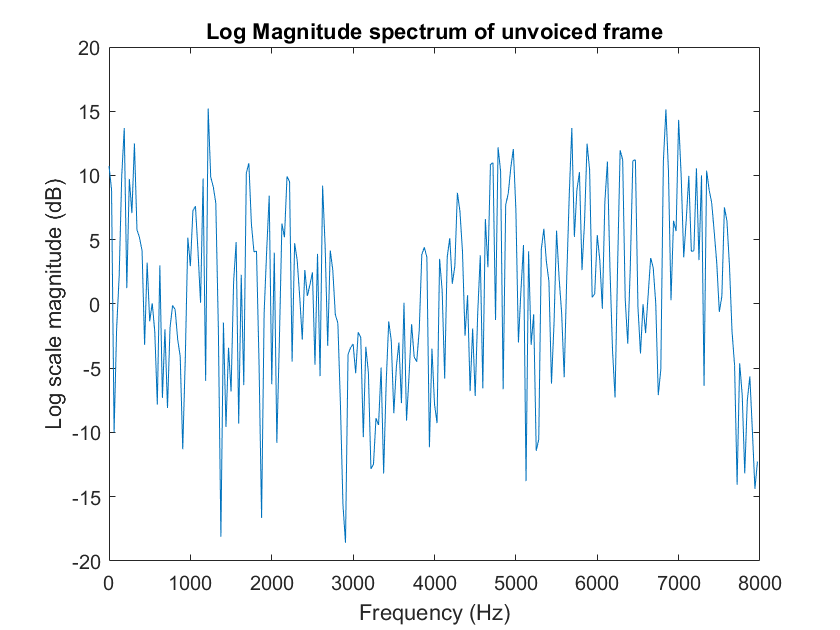

plot_freq_spectrum(unvoiced_frame, fs, 'Log Magnitude spectrum of unvoiced frame', 'log');

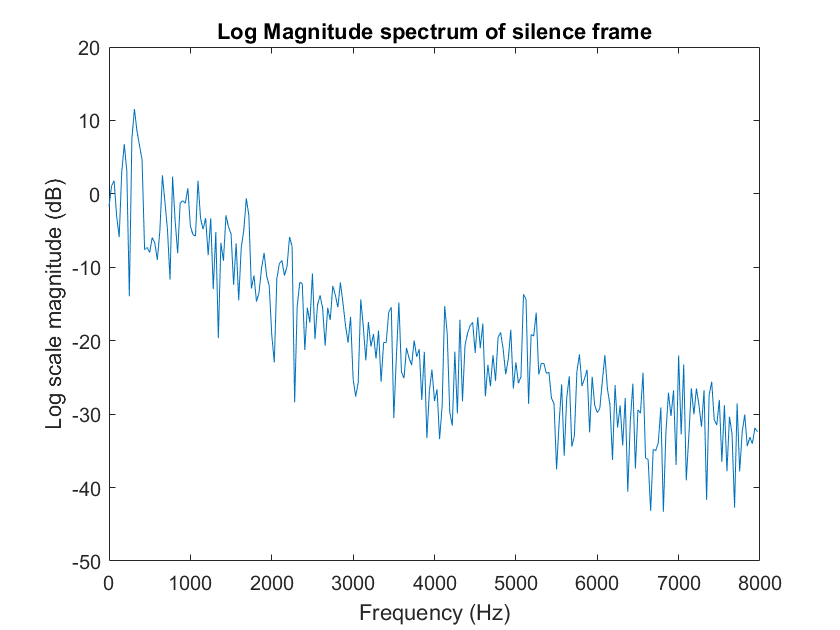

plot_freq_spectrum(silence_frame, fs, 'Log Magnitude spectrum of silence frame', 'log');

#### Observations:

By taking a small frame around the center, we can assume that this particular segment of speech to be stationary and appropriately do the spectral analysis in a much better way. Normally 10-30 ms frame size is used for quasi-stationarity assumption (here I am taking 20 ms frame size). By using STFT we can see the time-varying spectal information which is very much needed for the analysis of speech signals due it their non-stationary nature.

### C. Concept of true and convolved spectra:

a. Create a sine wave of 200Hz and compute DTFT of the whole signal. Now also compute the STFT by taking a 20-30ms short term segment of the sine wave. Explain your observation and difference between the true and convolved spectrum. 

### Theory:

STFT of speech involves convolution and might not give the intended information in the case for stationary signals. By taking a small segment of speech, we are basically multiplying by a rectangular window in time domain therefore we will undergo convolution in the frequency spectrum to get the convolved spectrum. In the case of sine signals, we observe a sinc function in the frequency domain due to convolution in the frequency domain (we are supposed to get only an impulse function). Thus there is a difference between convolved spectrum and true spectrum which we will get if we take the entire spectrum for this sine wave.

### Procedure:

We create a sine wave of 200 Hz frequency and plot its waveform and its linear and log magnitude spectrums.

### Code:

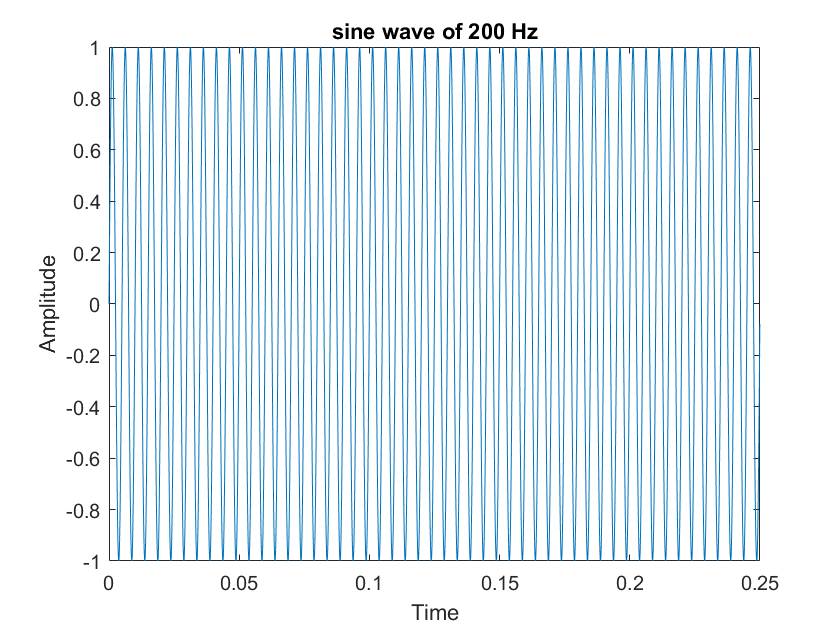

% fs = 1000; % Sampling frequency (Hz) (Given)
step = 1/fs; % Incremental Step
timeDuration = 0.25; % Total time duration of sine wave (Given)
t = (0:step:timeDuration-1/fs); % Time interval 
freq = 200; % Frequency (Hz) (Given)

% True spectrum
sineWave = sin(2*pi*freq*t);
plot_time_signal(sineWave, fs, 'sine wave of 200 Hz'); 

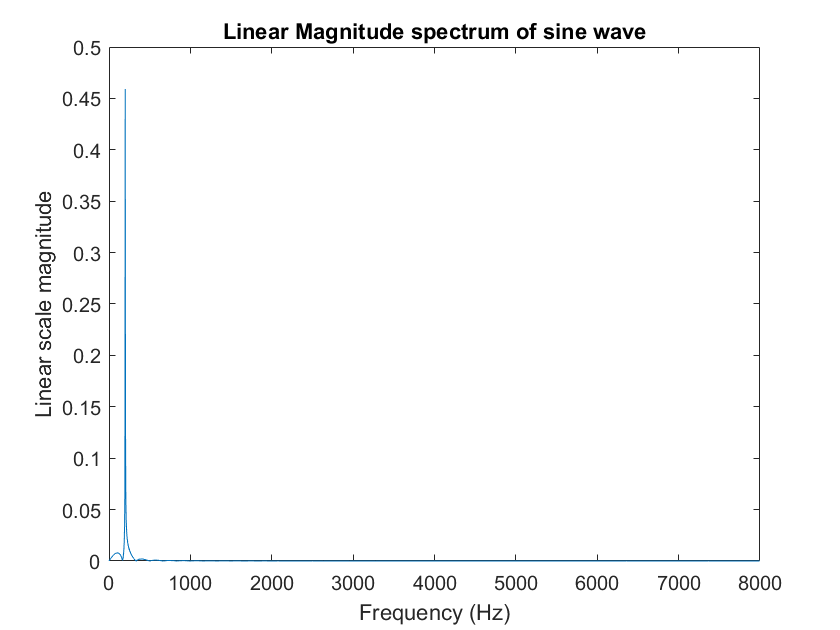


plot_freq_spectrum(sineWave, fs, 'Linear Magnitude spectrum of sine wave', 'linear');

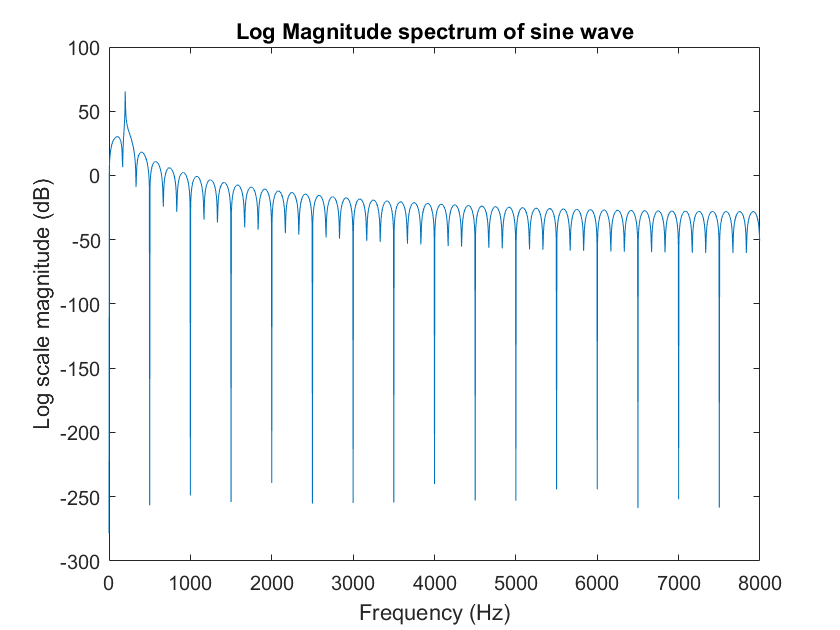

plot_freq_spectrum(sineWave, fs, 'Log Magnitude spectrum of sine wave', 'log');

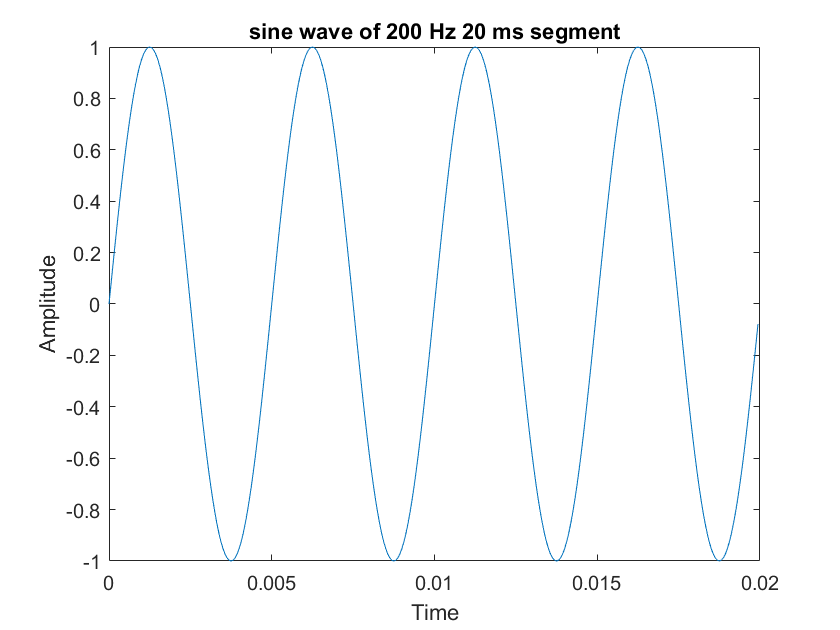

% convolved spectrum
sine_frame = sineWave(1:round(0.02*fs));
plot_time_signal(sine_frame, fs, 'sine wave of 200 Hz 20 ms segment'); 

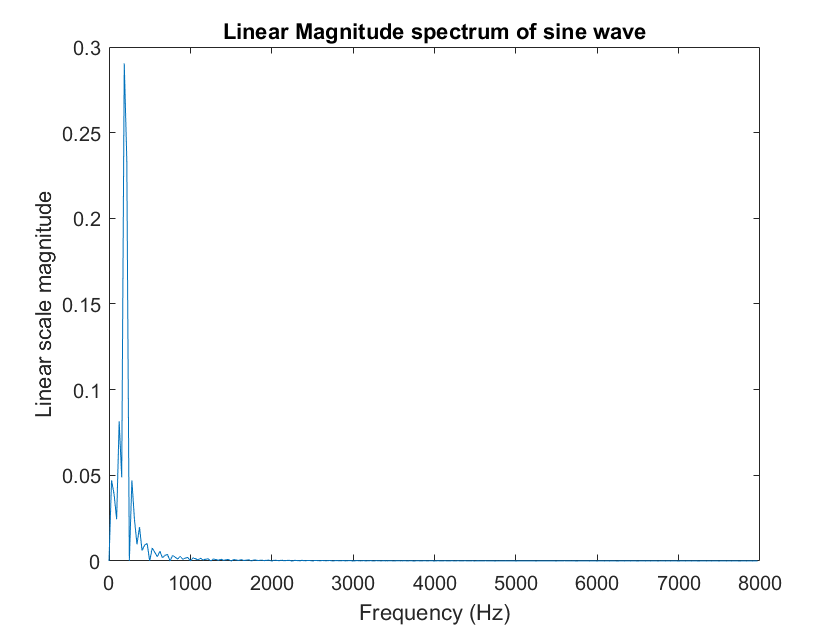


plot_freq_spectrum(sine_frame, fs, 'Linear Magnitude spectrum of sine wave', 'linear');

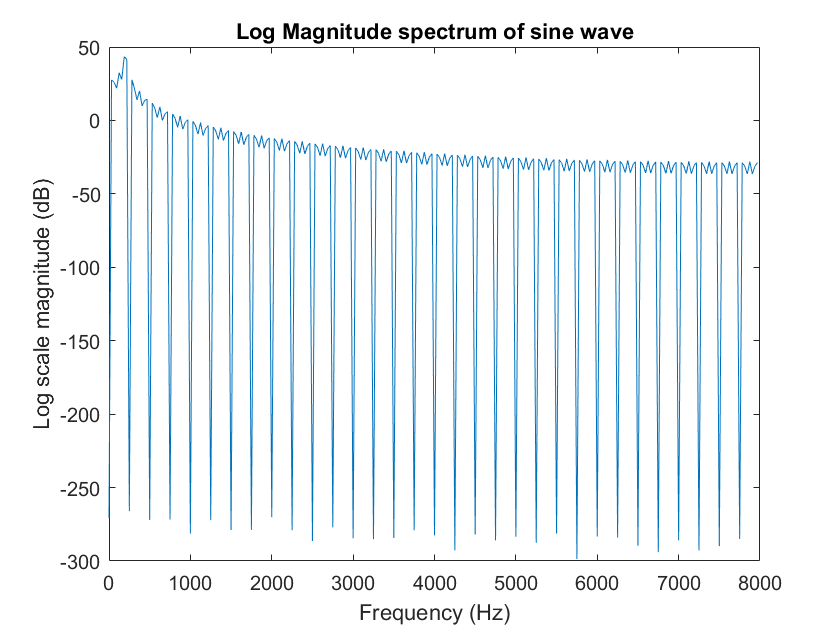

plot_freq_spectrum(sine_frame, fs, 'Log Magnitude spectrum of sine wave', 'log');

**Observations:**

We see that the convolved spectrum (taking a 20 ms segment of sine wave) is different from the true spectrum (taking the whole sine wave). We observe more frequency components with considerable magnitude in the case of the convolved spectrum (near the single impulse). Hence we see that STFT should be used accordingly and for this case it is not appropriate.

### D. Effect of windowing function and window size on short term spectral analysis: 

a. Plot short term log magnitude spectra of a 30 ms voiced speech segment using a rectangular, hamming and hanning window functions. Compare and write your observations in all the three cases.

b. Plot a short term log magnitude spectra of the voiced segment using a frame size of 3 ms, 30 ms and 300 ms. Compare and write your observations in all the three cases. 

### Theory:

As we take different segments of speech, we can use different windows such as rectangular, hamming and hanning windows which have different shapes and will vary the spectral information. Rectangular window provides better resolution due the main lobe width in the frequency domain being least but it has more spectral leakage which is not at all desirable hence in practice hamming and hanning windows are used.

### Procedure:

We take a voiced segment of 30 ms and plot the waveform and spectrum. We then apply different windows to this segment of speech and see the linear and log magnitude spectrum. Then we take different frame sizes

### Code:

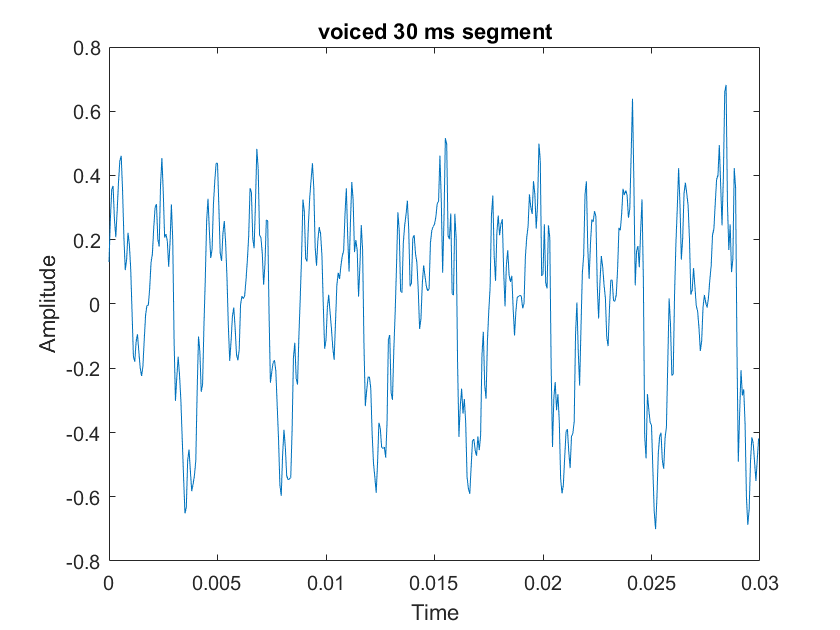

voiced_frame_30 = voiced_part(1:round(0.03*fs));
plot_time_signal(voiced_frame_30, fs, 'voiced 30 ms segment'); 

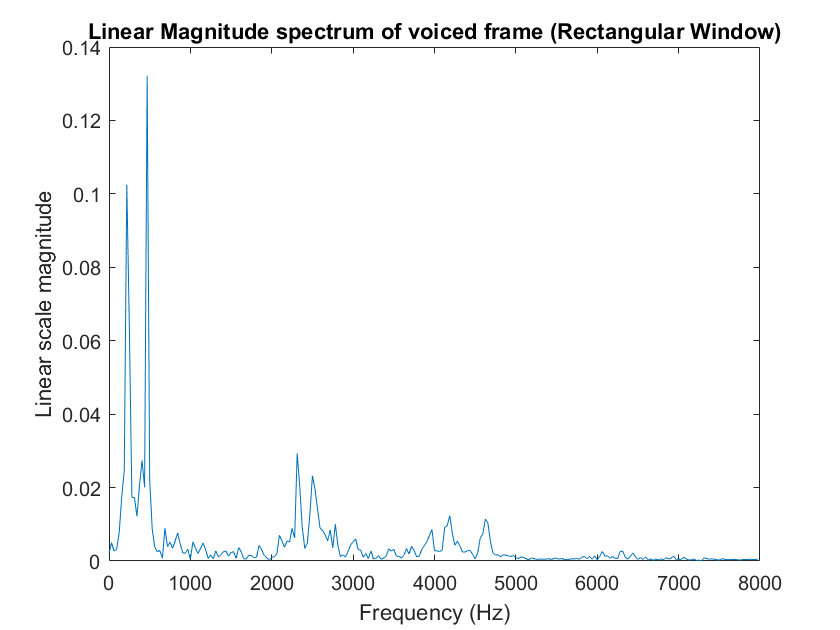


% Rectangular Window
plot_freq_spectrum(voiced_frame_30, fs, 'Linear Magnitude spectrum of voiced frame (Rectangular Window)', 'linear');

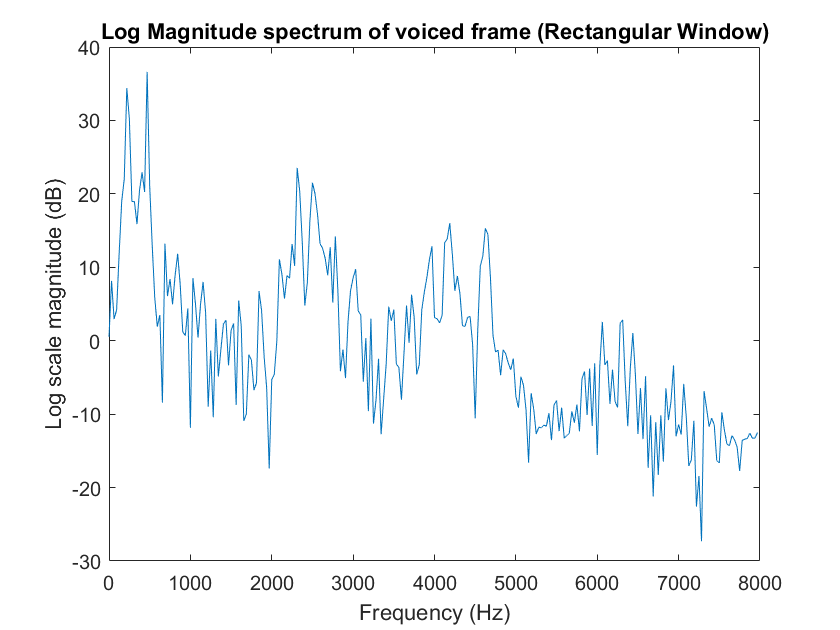

plot_freq_spectrum(voiced_frame_30, fs, 'Log Magnitude spectrum of voiced frame (Rectangular Window)', 'log');

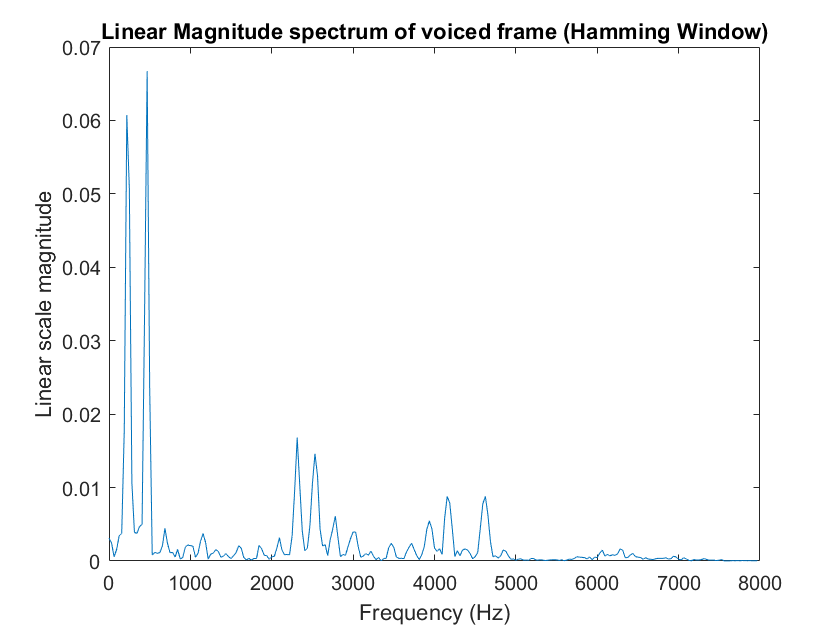


% Hamming window
win = dsp.Window("Hamming");
voiced_hamm = win(voiced_frame_30);
plot_freq_spectrum(voiced_hamm, fs, 'Linear Magnitude spectrum of voiced frame (Hamming Window)', 'linear');

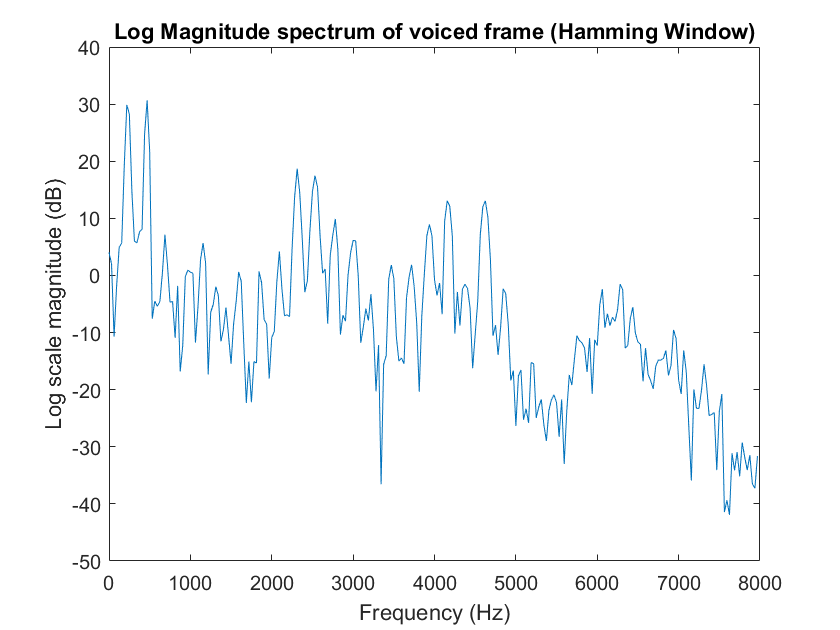

plot_freq_spectrum(voiced_hamm, fs, 'Log Magnitude spectrum of voiced frame (Hamming Window)', 'log');

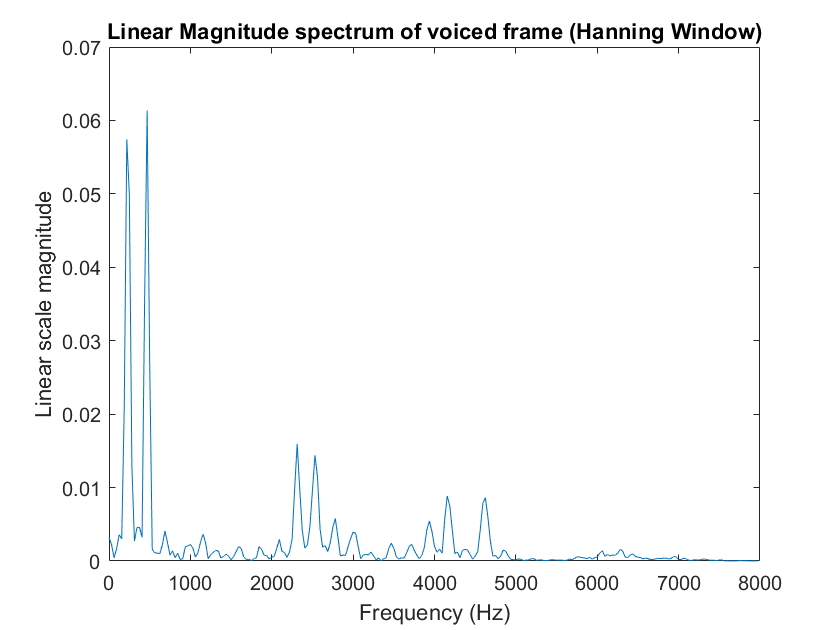


% Hanning window
win = dsp.Window("Hanning");
voiced_hann = win(voiced_frame_30);
plot_freq_spectrum(voiced_hann, fs, 'Linear Magnitude spectrum of voiced frame (Hanning Window)', 'linear');

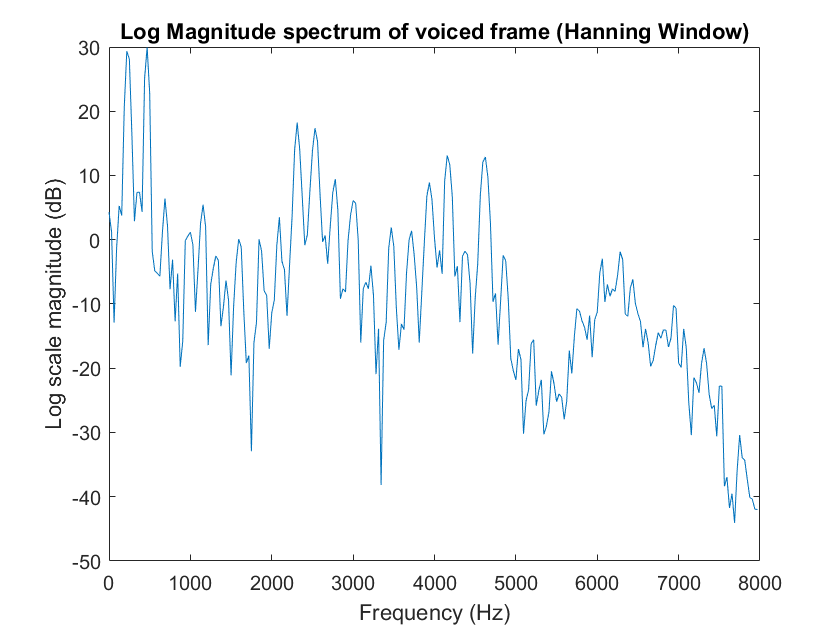

plot_freq_spectrum(voiced_hann, fs, 'Log Magnitude spectrum of voiced frame (Hanning Window)', 'log');

### Observations:

We see very sharp side peaks and much more noise when we use rectangular window whereas we see smoother peaks for hamming and hanning windows. This shows us the problem of spectral leakage in the case of rectangular window hence we use hamming and hanning window.

b)

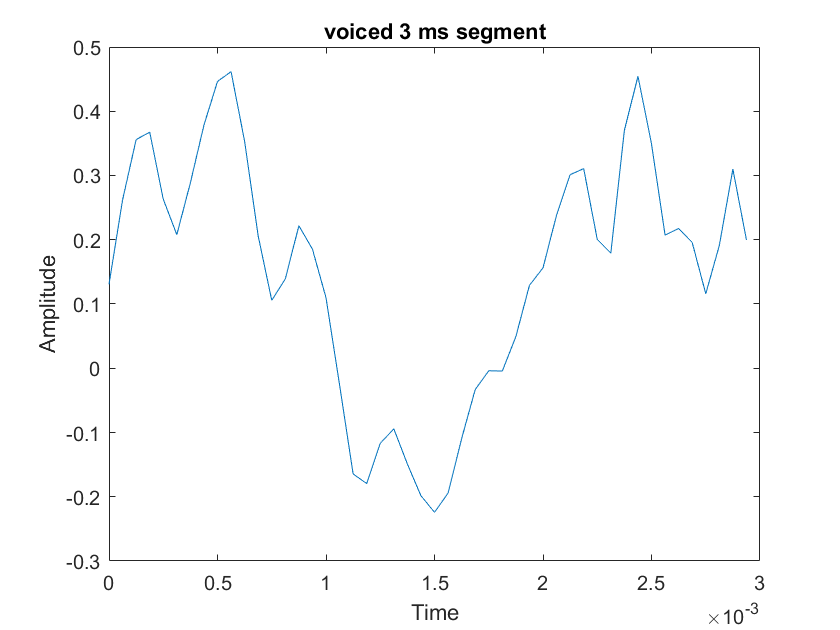

% 3 ms 
voiced_frame_3 = voiced_part(1:round(0.003*fs));
plot_time_signal(voiced_frame_3, fs, 'voiced 3 ms segment'); 

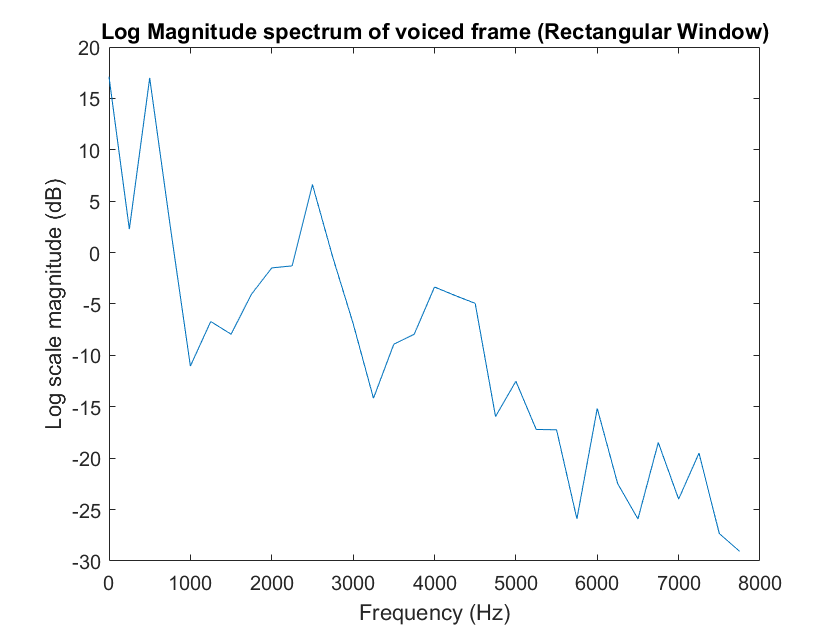


% Rectangular Window
plot_freq_spectrum(voiced_frame_3, fs, 'Log Magnitude spectrum of voiced frame (Rectangular Window)', 'log');

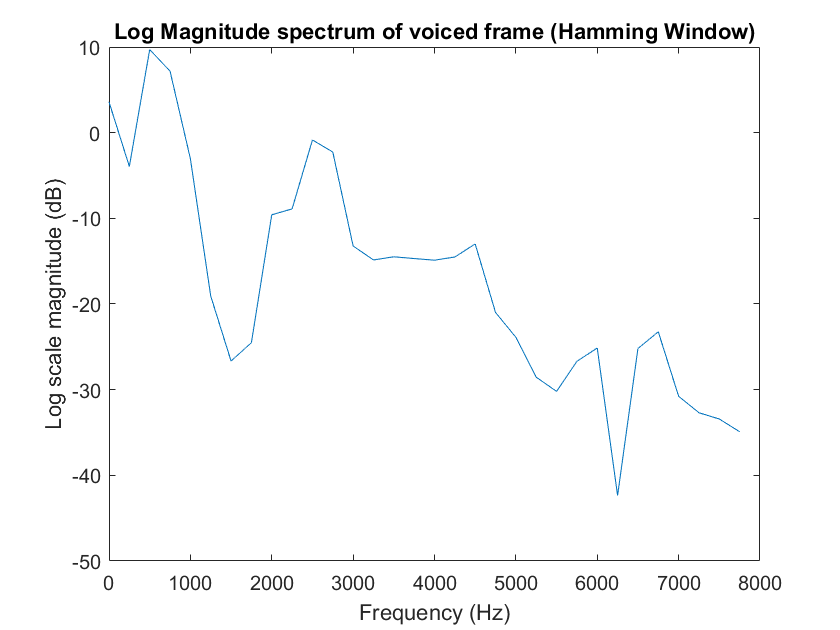


% Hamming window
win = dsp.Window("Hamming");
voiced_hamm = win(voiced_frame_3);
plot_freq_spectrum(voiced_hamm, fs, 'Log Magnitude spectrum of voiced frame (Hamming Window)', 'log');

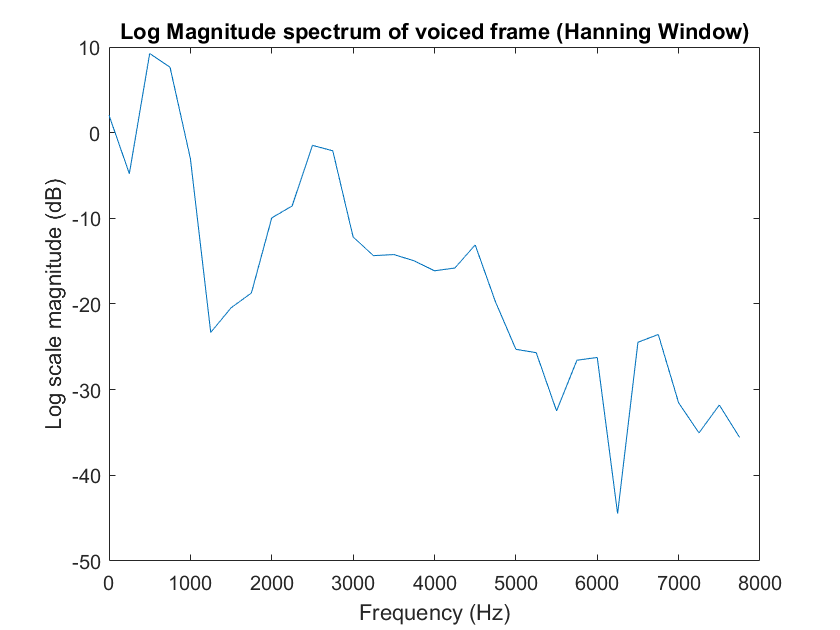


% Hanning window
win = dsp.Window("Hanning");
voiced_hann = win(voiced_frame_3);
plot_freq_spectrum(voiced_hann, fs, 'Log Magnitude spectrum of voiced frame (Hanning Window)', 'log');

% 30 ms
voiced_frame_30 = voiced_part(1:round(0.03*fs));
plot_time_signal(voiced_frame_30, fs, 'voiced 30 ms segment'); 


% Rectangular Window
plot_freq_spectrum(voiced_frame_30, fs, 'Log Magnitude spectrum of voiced frame (Rectangular Window)', 'log');


% Hamming window
win = dsp.Window("Hamming");
voiced_hamm = win(voiced_frame_30);
plot_freq_spectrum(voiced_hamm, fs, 'Log Magnitude spectrum of voiced frame (Hamming Window)', 'log');


% Hanning window
win = dsp.Window("Hanning");
voiced_hann = win(voiced_frame_30);
plot_freq_spectrum(voiced_hann, fs, 'Log Magnitude spectrum of voiced frame (Hanning Window)', 'log');

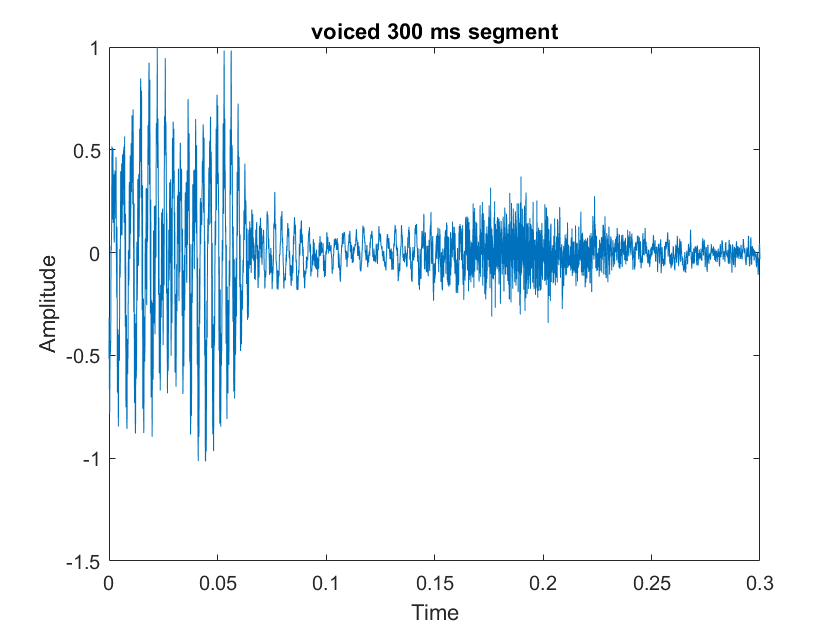

% 300 ms
voiced_frame_300 =  sound_sample(round(0.35*fs):round(0.35*fs)+round(0.3*fs));
plot_time_signal(voiced_frame_300, fs, 'voiced 300 ms segment'); 

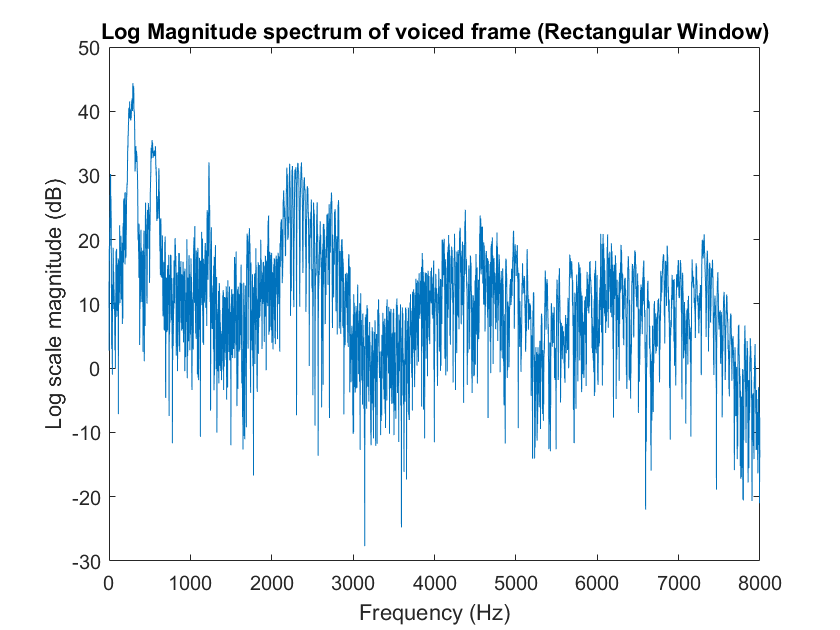


% Rectangular Window
plot_freq_spectrum(voiced_frame_300, fs, 'Log Magnitude spectrum of voiced frame (Rectangular Window)', 'log');

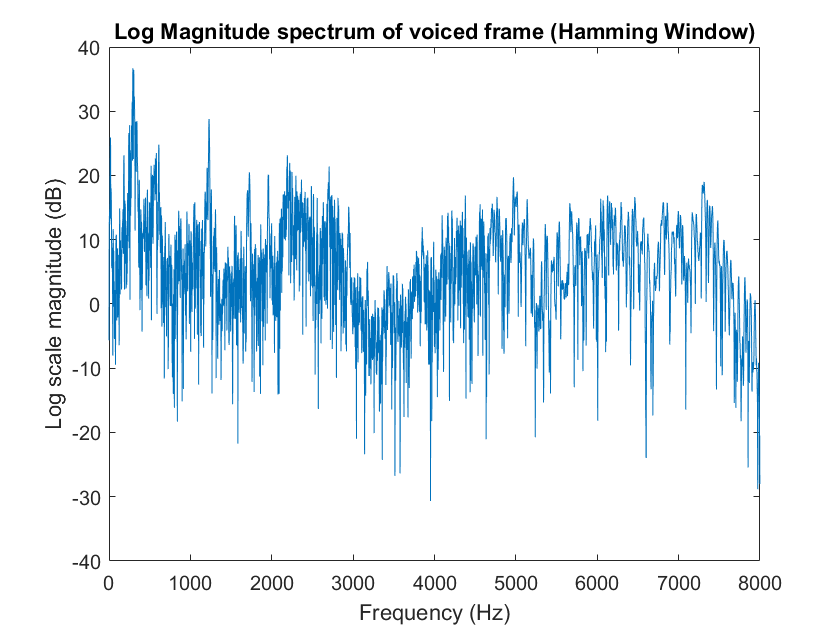


% Hamming window
win = dsp.Window("Hamming");
voiced_hamm = win(voiced_frame_300);
plot_freq_spectrum(voiced_hamm, fs, 'Log Magnitude spectrum of voiced frame (Hamming Window)', 'log');

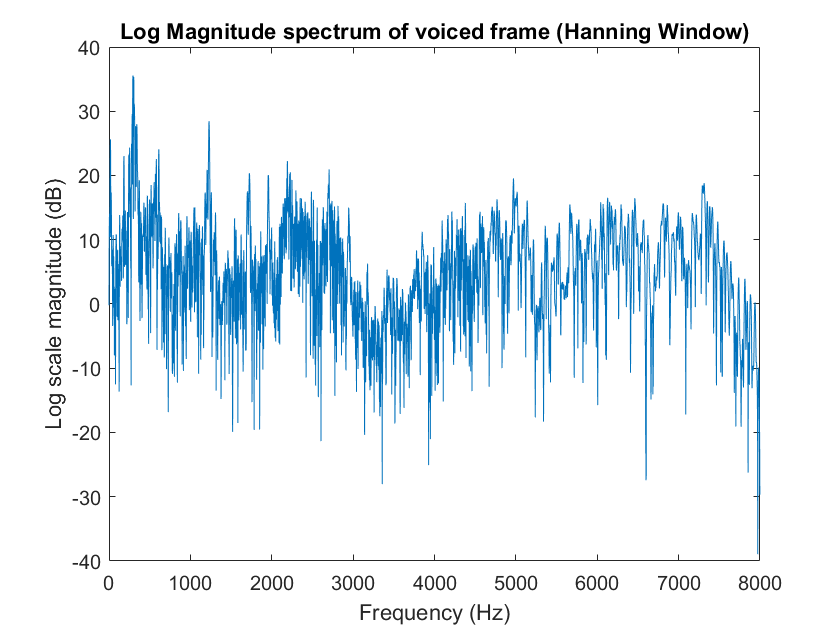


% Hanning window
win = dsp.Window("Hanning");
voiced_hann = win(voiced_frame_300);
plot_freq_spectrum(voiced_hann, fs, 'Log Magnitude spectrum of voiced frame (Hanning Window)', 'log');

### Observations:

We see that 3 ms size is too less (lesser than pitch period) hence might only show the vocal tract information. 30 ms size contains both vocal tract and excitation information (if we take envelope we get vocal tract information). 300 ms is too large and goes to even other regions (like unvoiced and silence regions), the time resolution in this case is very poor and it is not a good size to use. 

### Function Definitions

function plot_time_signal(y, fs, title_name)  % PLOT TIME DOMAIN PLOT FOR ANY SIGNAL
    plot((0:length(y)-1)/fs,y);
    xlabel("Time");
    ylabel("Amplitude");
    title(title_name);
end

function plot_freq_spectrum(x, fs, title_name, mode)
    N = length(x);
    n = pow2(nextpow2(N)); % Transforming the length so that the number of samples is a power of 2. 
    f = fs*[0: n-1]/n;
    if strcmp(mode, 'linear')
        X_mags = (abs(fft(x, n)));
        X_mags = X_mags/n;
        y_label = 'Linear scale magnitude';
    elseif  strcmp(mode, 'log')
        X_mags = 20*log10(abs(fft(x, n)));
        y_label = 'Log scale magnitude (dB)';
    end
    N_2 = ceil(n/2);
    plot(f(1:N_2), (X_mags(1:N_2)));
    xlabel('Frequency (Hz)')
    ylabel(y_label);
    title(title_name);
end